# Problem #1

A long distance commercial passenger aircraft has a typical crusing airspeed of** 880-926 km/h** (475-500 knots; 547-575 mph). In m/s this is **244-257 m/s**.

Therefore, at sea level condition (from Appendix A of textbook)


$$\begin{array}{l}
\rho_{\infty } =1\ldotp 2250\;\;\frac{\mathrm{kg}}{m^3 }\\
P_{\infty } =1\ldotp 01325\times {10}^5 \;\;\;\frac{N}{m^2 }
\end{array}$$



$$0\le V\le V_{\mathrm{max}} \;\;\;\Longrightarrow 0\le V\le 257\;\;\frac{m}{s}$$


From Bernoulli's Equation 


$$p=p_{\infty } \;+\;\frac{1}{2}\rho_{\infty } V_{\infty }^2$$


V_inf = 0:1:257;    % The cruising airspeed of the aircraft [m/s]
rho_inf = 1.2250;   % Freestream density at sea level [kg/m^3]
P_inf = 1.01325*10^5;   % Freestream pressure at sea level [N/m^3 or Pa]

Thus, using Bernoulli's Equation

% calculating the pressure meassured at the pitot tube (local pressure)
P_local = P_inf + 0.5 * rho_inf .* V_inf; 

also because the pressure coefficient is 


$$C_p =\frac{P\;-P_{\infty } }{\frac{1}{2}\rho_{\infty } V_{\infty \;}^2 }\;\;$$


% Calculating the pressure coefficient depending on the airspeed
C_p = (P_local - P_inf) / 0.5 / rho_inf ./ V_inf; 

Now, we plot a graph of local pressure by velocity/airspeed

and also the Cp (pressure coefficient by velocity/airspeed

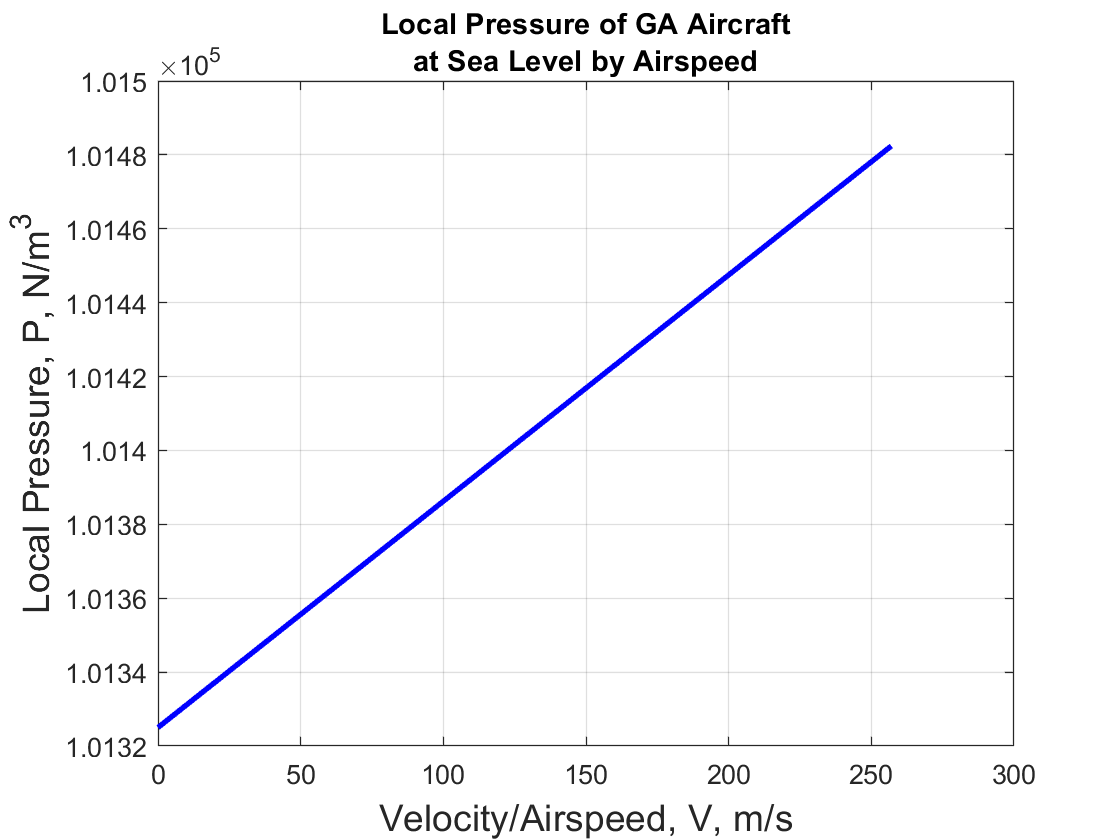

% Adjusting fontsize and linewidth
fontsize = 14;
linewidth = 2;

figure(1)
plot(V_inf, P_local, 'Color','b', 'LineStyle','-', 'LineWidth', linewidth)
title({'Local Pressure of GA Aircraft', 'at Sea Level by Airspeed'})
xlabel('Velocity/Airspeed, V, m/s', 'FontSize',fontsize)
ylabel('Local Pressure, P, N/m^3', 'FontSize',fontsize)
box on
grid on

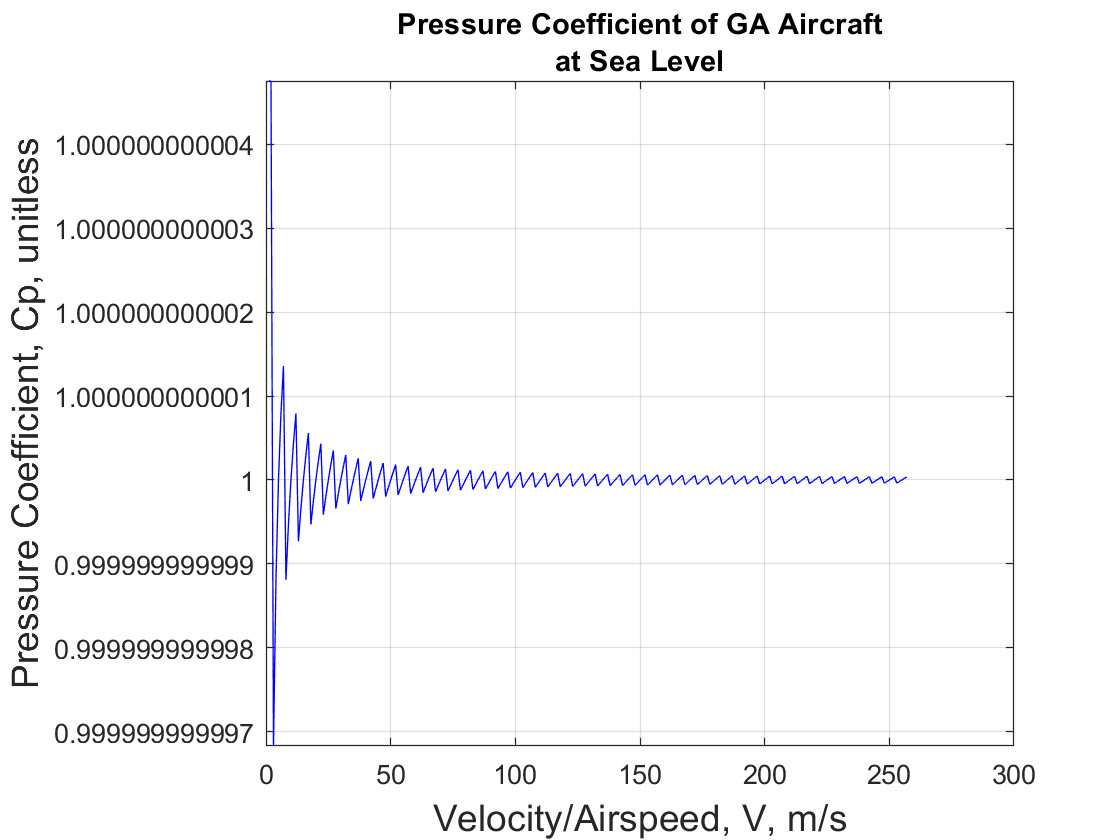


figure(2)
plot(V_inf, C_p,'Color','b', 'LineStyle','-')
title({'Pressure Coefficient of GA Aircraft', 'at Sea Level'})
xlabel('Velocity/Airspeed, V, m/s','FontSize',fontsize)
ylabel('Pressure Coefficient, Cp, unitless','FontSize',fontsize)
box on 
grid on

## Analysis:

-  What could the pressure coefficient be at the leading edge of the aircraft?

 ANS:    From the graph of the pressure coefficient, the Cp fluctuates with the value of 1 being the center. Therefore, the most plausible value for the coefficient is 1.

- How does it vary with airspeed? 

ANS:    As the velocity increases the pressure coefficient flucutuates while decreasing. And at maximum velocity it asymptotes to 1.